files = dir("split_output\*.csv")

files = 8×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


max_disp = zeros(length(files),1);
for i=1:length(files)
    file = files(i,:);
    data = readmatrix(strcat(file.folder,"\", file.name));
    max_disp(i) = max(data(:,2));
end
max_disp

max_disp =    18.9758
   19.9209
   20.9565
   20.1055
   20.1364
   21.0642
   22.6964
   20.1637


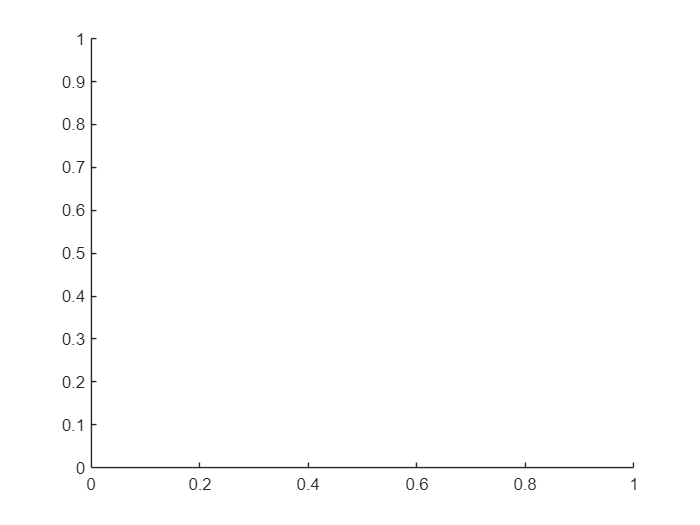

close all;
figure()
hold on;

for i = 1:length(files)
    file = files(i,:);
    data = readmatrix(strcat(file.folder,"\", file.name));
    plot(data(:,1),data(:,2),'DisplayName',file.name);
end

Unrecognized function or variable 'files'.

legend()


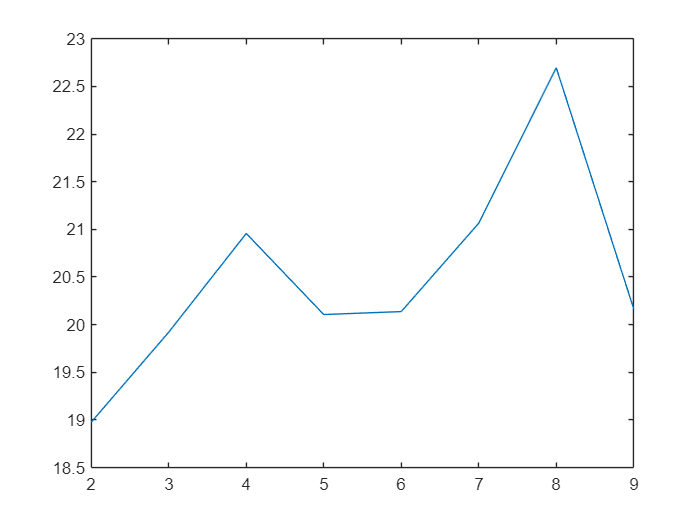

figure()
mps = (2:(length(files)+1));
plot(mps,max_disp)